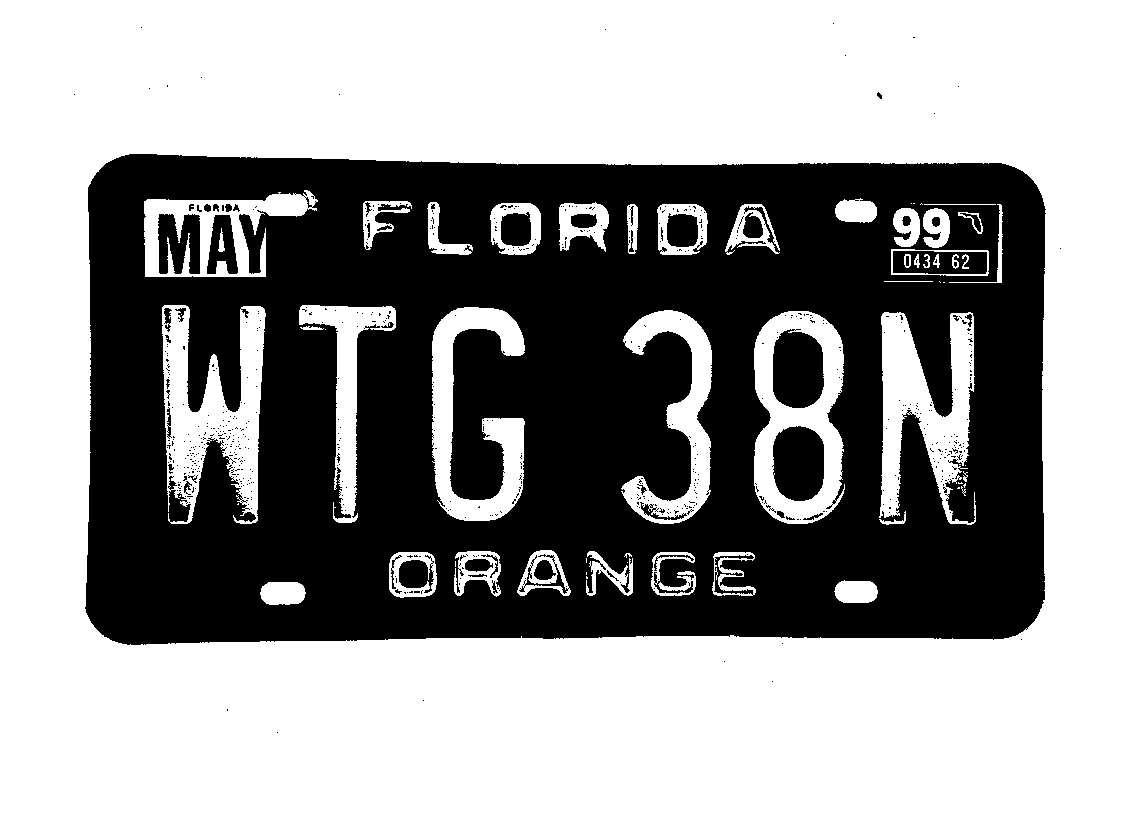

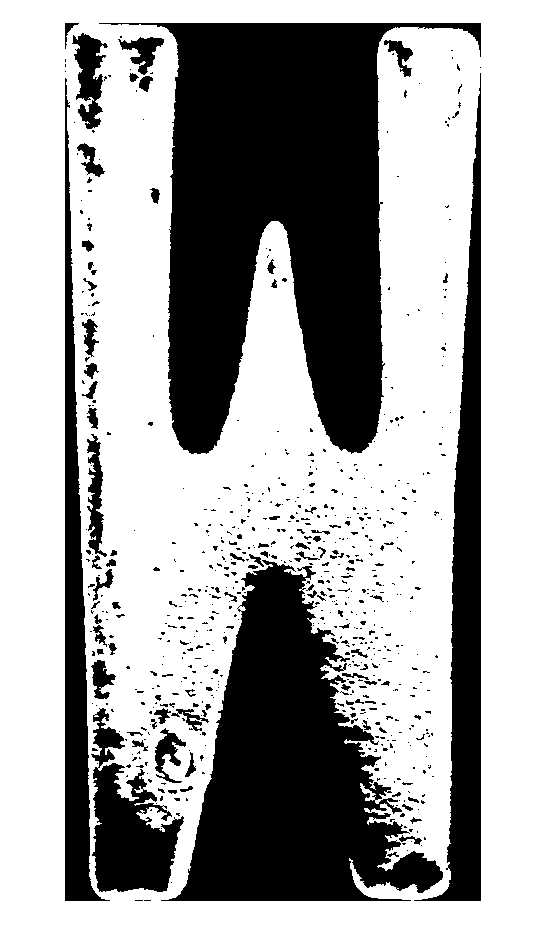

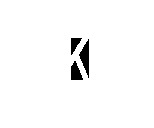

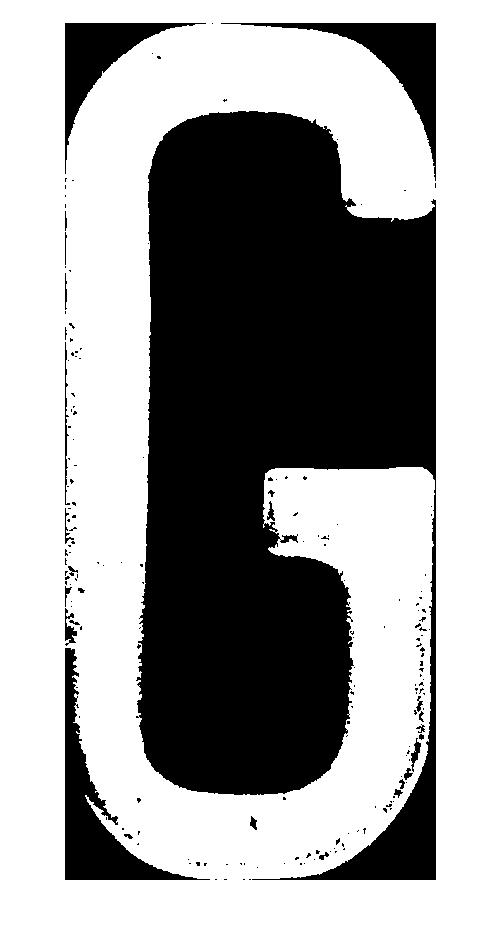

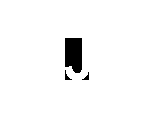

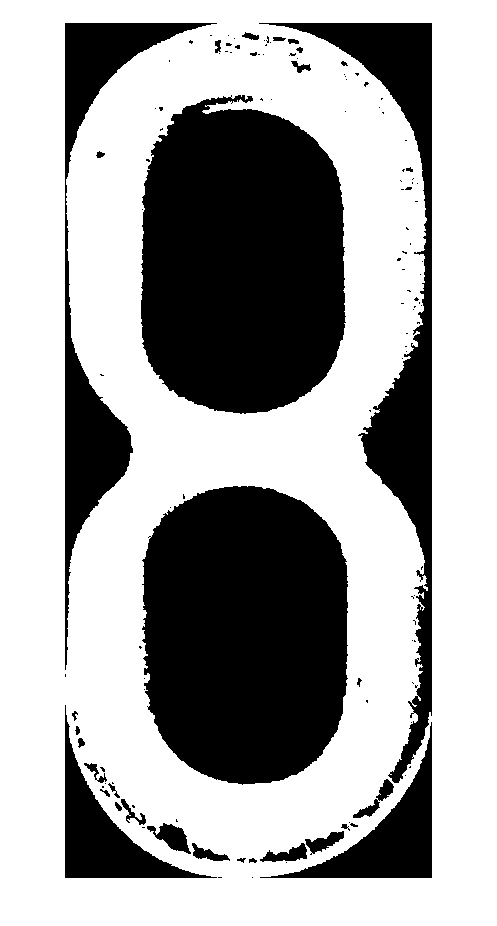

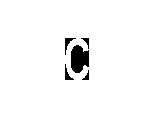

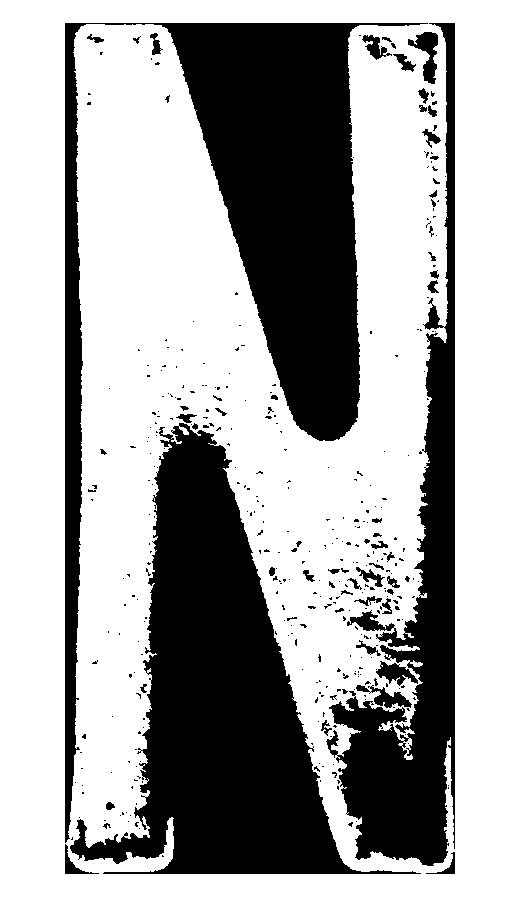


D = 'MLab/';
p = "WTG38N.jpg";
S = dir(fullfile(D,p));

totalPlates = numel(S);
counterFoundCorrectly = 0;
counterListByElements = [0,0,0,0,0,0];

for k = 1:numel(S)
    F = fullfile(D,S(k).name);
    I = imread(F);
    
    imgray = rgb2gray(I);
    I = imbinarize(imgray);
    
    I = bwareaopen(~I, 500);
    
    [h, w] = size(I);
   
    %read letter
    Iprops=regionprops(I,'BoundingBox','Area', 'Image');
    count = numel(Iprops);
    
    noPlate=[]; % Initializing the variable of number plate string.
    
    imshow(I);
    figure;
    
    for i=1:count
        
       propWidth = length(Iprops(i).Image(1,:));
       propHeight = length(Iprops(i).Image(:,1));
       
       if propWidth > 200 && propHeight > 750
           letter=readLetter(Iprops(i).Image); % Reading the letter corresponding the binary image 'N'.
           
           if letter ~= '-'
              figure; 
              imshow(Iprops(i).Image);
              figure; 
              imageName = imread(['char/',letter,'.bmp']);
              imshow(imageName);
           end
           noPlate=[noPlate letter]; % Appending every subsequent character in noPlate variable.  

       end
    end
    
    if numel(noPlate) > 0  
        
      elementsCorrectly = 0;  
      for i=1:numel(noPlate)
          if noPlate(i) == S(k).name(i)
               elementsCorrectly = elementsCorrectly + 1;
          end
      end
      
      if elementsCorrectly > 0 
         counterListByElements(elementsCorrectly) = counterListByElements(elementsCorrectly) + 1;
      end
    end

    figure;
end 



disp('The result is:');

The result is:


disp([' - Number of plates: ', num2str(totalPlates)]);

 - Number of plates: 1


disp([' - Number of plates recognized: ', num2str(counterFoundCorrectly)]);

 - Number of plates recognized: 0



disp(' ');


disp('Plates by num of letters recognized incompletly:');

Plates by num of letters recognized incompletly:


for i=1:numel(counterListByElements)
    disp(['Letters: ', num2str(i), ', Plates: ', num2str(counterListByElements(i))])
end

Letters: 1, Plates: 0
Letters: 2, Plates: 0
Letters: 3, Plates: 0
Letters: 4, Plates: 0
Letters: 5, Plates: 0
Letters: 6, Plates: 0
